# **Lorentz Problem for various Initial conditions**

clear variables
clc
close all

## Defining constants

sigma=10;
beta=8/3;
rho=28;

## Single Initial condition for RK4

x0=[-8;8;27];
dt=0.01;
tspan=0:dt:4;
X(:,1)=x0;
xin=x0;
for i=1:tspan(end)/dt
    time=i*dt;
    xout=rk4singlestep(@(t,x)lorentz_function(t,x,sigma,beta,rho),dt,time,xin);
    X=[X xout];
    xin=xout;
end

## Single Initial condition for ODE45

[t,x]=ode45(@(t,x)lorentz_function(t,x,sigma,beta,rho),tspan,x0)

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x =    -8.0000    8.0000   27.0000
   -6.4864    7.8032   25.7255
   -5.1379    7.5633   24.6089
   -3.9411    7.3137   23.6289
   -2.8815    7.0778   22.7653
   -1.9441    6.8727   22.0007
   -1.1137    6.7087   21.3199
   -0.3750    6.5910   20.7104
    0.2845    6.5226   20.1628
    0.8768    6.5049   19.6701


## Cube of Initial conditions for RK4

xvec=-20:1:20;
yvec=-20:1:20;
zvec=-20:1:20;
[x0_v,y0_v,z0_v]=meshgrid(xvec,yvec,zvec);
xIC(1,:,:,:)=x0_v;
xIC(2,:,:,:)=y0_v;
xIC(3,:,:,:)=z0_v;

## Video forming

dt=0.01;
duration=4;
tspan=[0,duration];
L=duration/dt;
xin=xIC;
videoFile = 'lorentz_animation.mp4';  
writerObj = VideoWriter(videoFile, 'MPEG-4');
open(writerObj);

## Time Iteration

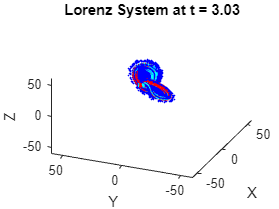

for step=1:L
    time=step*dt;
    xout=rk4singlestep(@(t,x)lorentz3d_function(t,x,sigma,beta,rho),dt,time,xin);
    xin=xout;
    plot3(X(1,:),X(2,:),X(3,:),'r','Linewidth',3) % My RK4 Plot
    hold on
    plot3(x(:,1),x(:,2),x(:,3),'c','LineWidth',3) % ODE45 Plot
    plot3(xout(1,:),xout(2,:),xout(3,:),'b.','MarkerSize',2) % Multiple Initial conditions Plot
    axis([-60 60 -60 60 -60 60])
    view([20+360*step/L, 40]);
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title(['Lorenz System at t = ' num2str(time)]);
    set(gca,'Fontsize',10)
    frame = getframe(gcf);
    writeVideo(writerObj, frame);
    hold off
end


close(writerObj);